clear
signal_freq = 20000

signal_freq = 20000

del = true;
show_sin = true;
[fs, f, filename, lim, phase_shift,f_fig] = setParams(signal_freq, del, show_sin);
disp(['Fs=', num2str(fs)]);

Fs=776.5


**Построение графиков**

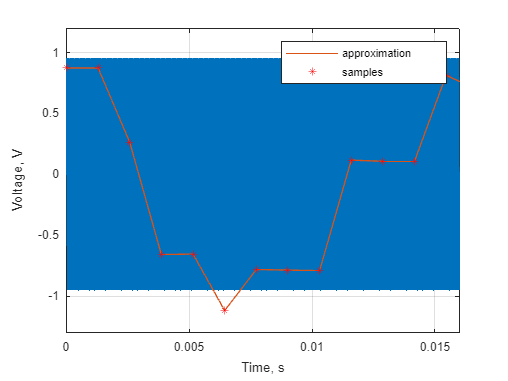

data = readmatrix(filename, 'NumHeaderLines', 1);
sig = data;

n_samples = length(sig);
time_vec = (0:n_samples-1)/fs;

sig = sig*(5/1024) - 1.5;

t = 0:0.00001:10;
sine = sin(2*pi*f_fig*(t + phase_shift));

plot(t, sine, 'HandleVisibility','off');
hold on;
plot(time_vec, sig);
hold on;
plot(time_vec, sig, 'r*');

grid on;
xlabel('Time, s');
ylabel('Voltage, V');
legend('approximation', 'samples');
xlim([0 lim]);
ylim([-1.3 1.2]);

**Амплитудный спектр сигнала**

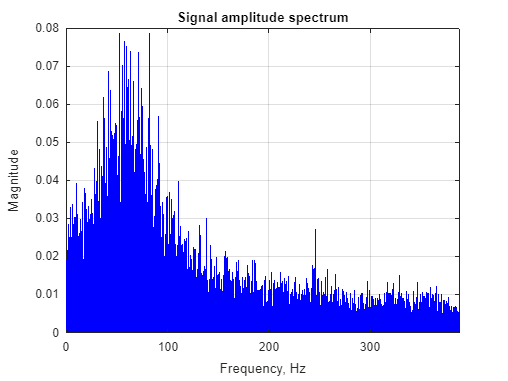

sig = sig - mean(sig);
sig_fft = fft(sig);
sig_fft_mag = abs(sig_fft)/(n_samples/2);

f_vec = (0:n_samples-1)*(fs/n_samples);
half_vec = 1:round(n_samples/2);

figure;
stem(f_vec(half_vec), sig_fft_mag(half_vec), 'b', 'Marker','none');
grid on;
xlabel('Frequency, Hz');
ylabel('Magnitude');
title('Signal amplitude spectrum');
xlim([0 fs/2]);


[~, idx_max_sig] = max(sig_fft_mag(half_vec));
freq_max_sig = f_vec(idx_max_sig);

**Фазовый спектр сигнала**

sig_fft_phase = angle(sig_fft);

figure;
stem(f_vec(half_vec), sig_fft_phase(half_vec), 'b');
hold on;
grid on;
xlabel('Frequency, Hz');
ylabel('Phase, Rad');
title('Signal phase spectrum');
stem(freq_max_sig, sig_fft_phase(idx_max_sig), 'r', 'LineWidth', 2, 'Marker', 'none');
xlim([freq_max_sig-3, freq_max_sig+3]);

**Теоретический амплитудный спектр синусоидального сигнала**

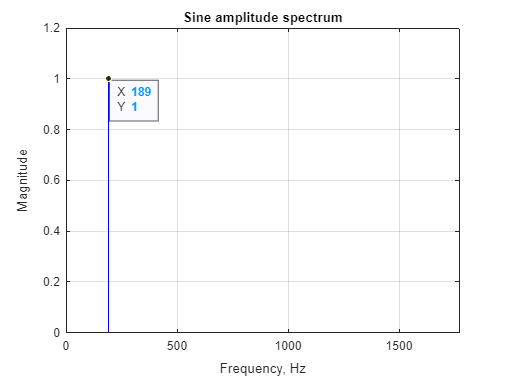

b_vec = 0:1/fs:10-1/fs;
sine = sin(2*pi*f.*b_vec);

n_sine = length(sine);
sine_fft = fft(sine);
sine_fft_mag = abs(sine_fft)/(n_sine/2);

f_sine_vec = (0:n_sine-1)*(fs/n_sine);
half_sine = 1:round(n_sine/2);

figure;
stem(f_sine_vec(half_sine), sine_fft_mag(half_sine), 'b', 'Marker','none');
grid on;
xlabel('Frequency, Hz');

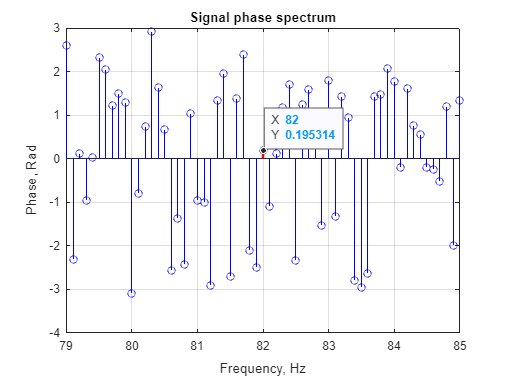

ylabel('Magnitude');
title('Sine amplitude spectrum');
xlim([0 fs/2]);
ylim([0 1.2]);


xlim([0 1772])
ylim([0.00 1.20])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,250,1);

[~, idx_max_sine] = max(sine_fft_mag(half_sine));
sine_freq_max = f_sine_vec(idx_max_sine);


**Теоретический фазовый спектр синусоидального сигнала**

При Fs/F > 2 phase = -pi/2 

При Fs/F < 2 phase = pi/2

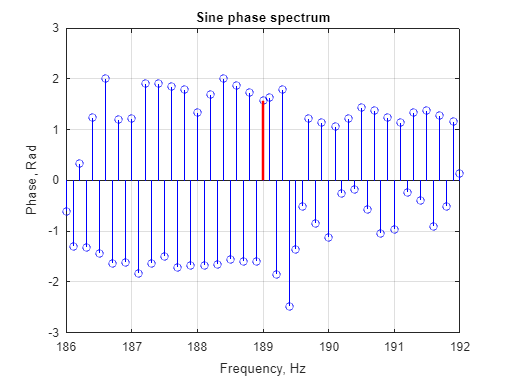

sine_fft_phase = angle(sine_fft);

figure;

stem(f_sine_vec(half_sine), sine_fft_phase(half_sine), 'b');
hold on;
grid on;
xlabel('Frequency, Hz');
ylabel('Phase, Rad');
title('Sine phase spectrum');
stem(sine_freq_max, sine_fft_phase(idx_max_sine), 'r', 'LineWidth', 2, 'Marker', 'none');
xlim([sine_freq_max-3, sine_freq_max+3]);

**Амплитудный спектр сигнала с использованием оконной функции Хемимнга на интервале в один период**

% if fs/f >= 2
%     n_sig_period = round(fs/f);
% else
%     n_sig_period = 10;
% end
% 
% sig_period = sig(1:n_sig_period);
% hamming_sig_win = hamming(n_sig_period);
% sig_ham_win = sig_period .* hamming_sig_win;
% 
% sig_ham_fft = fft(sig_ham_win);
% sig_ham_fft_mag = abs(sig_ham_fft)/(sum(hamming_sig_win)/2);
% 
% f_sig_ham_vec = (0:n_sig_period-1)*(fs/n_sig_period);
% half_sig_ham = 1:max(1, round(n_sig_period/2));
% 
% figure;
% stem(f_sig_ham_vec(half_sig_ham), sig_ham_fft_mag(half_sig_ham), 'b');
% grid on;
% xlabel('Frequency, Hz');
% ylabel('Magnitude');
% title('Amplitude spectrum Hamming window');
% xlim([0 fs/2]);
% 
% [~, idx_max_sig_ham] = max(sig_ham_fft_mag(half_sig_ham));
% freq_max_sig_ham = f_sig_ham_vec(half_sig_ham(idx_max_sig_ham));

**Фазовый спектр сигнала с использованием оконной функции Хемимнга на интервале в один период**

% sig_ham_fft_phase = angle(sig_ham_fft);
% 
% figure;
% stem(f_sig_ham_vec(half_sig_ham), sig_ham_fft_phase(half_sig_ham), 'b');
% hold on;
% grid on;
% xlabel('Frequency, Hz');
% ylabel('Phase, Rad');
% title('Signal phase spectrum using Hamming window');
% xlim([freq_max_sig_ham-3, freq_max_sig_ham+3]);

**Теоретический амплитудный спектр сигнала с использованием оконной функции Хемимнга на интервале в один период**

% if fs/f >= 2
%     n_sine_period = round(fs/f);
% else
%     n_sine_period = 10;
% end
% 
% t_sine = (0:n_sine_period-1)/fs;
% sine_one_period = sin(2*pi*f.*t_sine);
% hamming_sine_win = hamming(length(sine_one_period))';
% sine_ham_win = sine_one_period .* hamming_sine_win;
% 
% n_sine_win = length(sine_ham_win);
% sine_ham_fft = fft(sine_ham_win);
% sine_ham_fft_mag = abs(sine_ham_fft)/(sum(hamming_sine_win)/2);
% 
% f_sine_ham_vec = (0:n_sine_win-1)*(fs/n_sine_win);
% half_sine_ham = 1:round(n_sine_win/2);
% 
% figure;
% stem(f_sine_ham_vec(half_sine_ham), sine_ham_fft_mag(half_sine_ham), 'b');
% grid on;
% xlabel('Frequency, Hz');
% ylabel('Magnitude');
% title('Sine amplitude spectrum using Hamming window');
% xlim([0 fs/2]);
% ylim([0 1.2]);
% 
% [~, idx_max_sine_ham] = max(sine_ham_fft_mag(half_sine_ham));
% sine_freq_max_ham = f_sine_ham_vec(idx_max_sine_ham);

**Теоретический фазовый спектр сигнала с использованием оконной функции Хемимнга на интервале в один период**

% sine_ham_fft_phase = angle(sine_ham_fft);
% 
% figure;
% stem(f_sine_ham_vec(half_sine_ham), sine_ham_fft_phase(half_sine_ham), 'b');
% hold on;
% grid on;
% xlabel('Frequency, Hz');
% ylabel('Phase, Rad');
% title('Sine phase spectrum using Hamming window');
% xlim([sine_freq_max_ham-3, sine_freq_max_ham+3]);